EEE Subject 1 Total Effect Readout:

cd('C:\Users\bgrau\GitHub\ieeg_affect\EEE\subjects\sub-01\ses-01')
% clear all
load('stim_table_full.mat')
stim_table = movevars(stim_table, 'val_rating', 'After', 'cue_observed_mean');
% stim_table = stim_table(:, [1:4 6:9 11 12 14 15 31 33]);

cs = find(contains(stim_table.Properties.VariableNames, 'mean'));
stim_table{:,cs} = (stim_table{:,cs} - 1)/6*100;

cs = find(contains(stim_table.Properties.VariableNames, 'SD'));
stim_table{:,cs} = (stim_table{:,cs})/6*100;

cs = find(contains(stim_table.Properties.VariableNames, 'std'));
stim_table{:,cs} = (stim_table{:,cs})/6*100;

cs = find(contains(stim_table.Properties.VariableNames, 'difference'));
stim_table{:,cs} = (stim_table{:,cs})/6*100;

cs = find(contains(stim_table.Properties.VariableNames, 'deviation'));
stim_table{:,cs} = (stim_table{:,cs})/6*100;

cs = find(contains(stim_table.Properties.VariableNames, 'rating'));
stim_table{:,cs} = (stim_table{:,cs} - 1)/6*100;



stim_table = sortrows(stim_table,"Pair","ascend");


cuehl = stim_table.highcue_indx;
cuemean = stim_table.cue_observed_mean;
pair = stim_table.Pair;
rating = stim_table.val_rating;
stimmean = stim_table.Valence_mean;



wh_high = cuehl > 0;
wh_low = cuehl < 0;

hi_table = stim_table(wh_high, :);
lo_table = stim_table(wh_low, :);


pair_table = table;
pair_table.pair_number = hi_table.Pair;
pair_table.hi_val = hi_table.val_rating;
pair_table.lo_val = lo_table.val_rating;
pair_table.hi_exp = hi_table.exp_rating;
pair_table.lo_exp = lo_table.exp_rating;
pair_table.exp_mean = (pair_table.hi_exp + pair_table.lo_exp) /2;
pair_table.rating_mean = (hi_table.val_rating + lo_table.val_rating)/2;
pair_table.cue_mean = (hi_table.cue_observed_mean + lo_table.cue_observed_mean)/2;
pair_table.cue_sd = (hi_table.cue_observed_std + lo_table.cue_observed_std)/2;
pair_table.stim_mean = (hi_table.Valence_mean + lo_table.Valence_mean)/2;
pair_table.stim_sd = (hi_table.Valence_SD + lo_table.Valence_SD)/2;
pair_table.rating_diff = hi_table.val_rating - lo_table.val_rating;
pair_table.stim_diff = (hi_table.Valence_mean - lo_table.Valence_mean);
d = pair_table.rating_diff;

% Two-tailed
[hyp, pval, ci, stat] = ttest(hi_table.val_rating, lo_table.val_rating, 'Tail', 'right');
fprintf('High vs. low cue effect: M = %3.2f, SE = %3.2f, t(%3.0f) = %3.2f, p = %3.6f\n', mean(d), ste(d), stat.df(1), stat.tstat(1), pval(1));

High vs. low cue effect: M = 6.66, SE = 2.39, t( 31) = 2.78, p = 0.004580


Cue Effect (ordered by pair number)

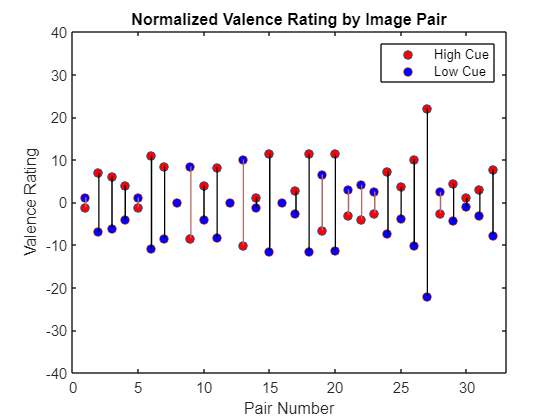


cuecolors = {[1 0 0] [0 0 1]};


y = [pair_table.hi_val-pair_table.rating_mean pair_table.lo_val-pair_table.rating_mean];  % ratings, [high low]
x = [pair_table.pair_number pair_table.pair_number];  % pairs, [high low]


highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

% meandots = plot(pair_table.cue_mean, 'o', 'MarkerFaceColor', 'g');


d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);

xlabel('Pair Number');
ylabel('Valence Rating');
title('Normalized Valence Rating by Image Pair')
axis([0 33 -40 40])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

hold off;

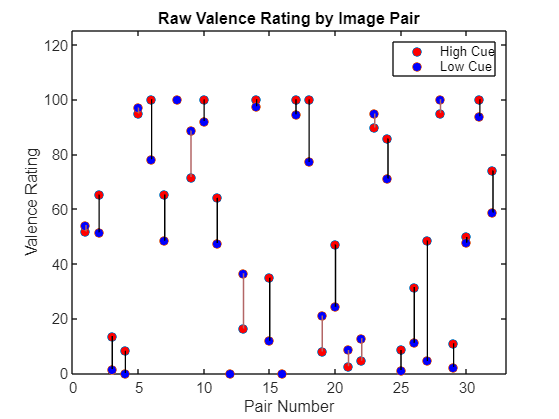


cuecolors = {[1 0 0] [0 0 1]};


y = [pair_table.hi_val pair_table.lo_val];  % ratings, [high low]
x = [pair_table.pair_number pair_table.pair_number];  % pairs, [high low]


highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

% meandots = plot(pair_table.cue_mean, 'o', 'MarkerFaceColor', 'g');


d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);

xlabel('Pair Number');
ylabel('Valence Rating');
title('Raw Valence Rating by Image Pair')
axis([0 33 0 125])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

hold off;

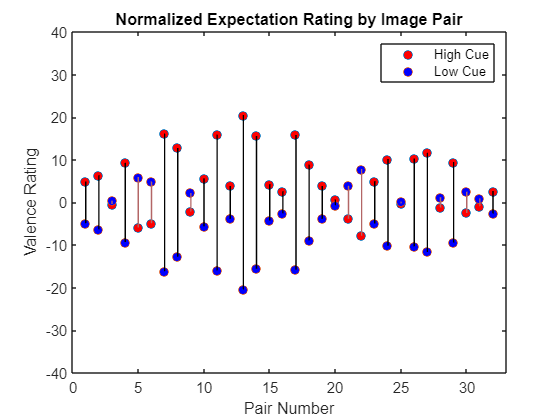



y = [pair_table.hi_exp-pair_table.exp_mean pair_table.lo_exp-pair_table.exp_mean];  % ratings, [high low]
x = [pair_table.pair_number pair_table.pair_number];  % pairs, [high low]


highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);

xlabel('Pair Number');
ylabel('Valence Rating');
title('Normalized Expectation Rating by Image Pair')
axis([0 33 -40 40])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

hold off;

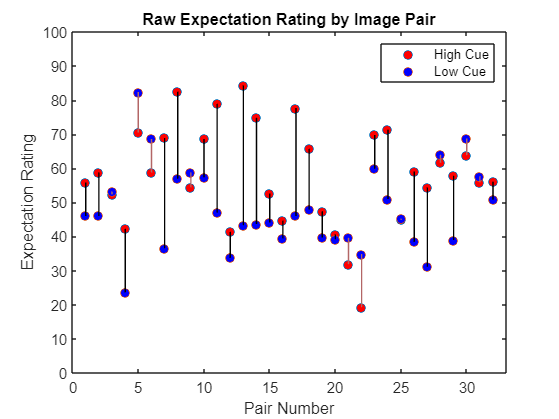


y = [pair_table.hi_exp pair_table.lo_exp];  % ratings, [high low]
x = [pair_table.pair_number pair_table.pair_number];  % pairs, [high low]


highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

% meandots = plot(pair_table.cue_mean, 'o', 'MarkerFaceColor', 'g');


d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);

xlabel('Pair Number');
ylabel('Expectation Rating');
title('Raw Expectation Rating by Image Pair')
axis([0 33 0 100])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

hold off;

g = gramm('x', pair_table.pair_number, 'y', d);
    % g.stat_violin('fill', 'transparent');
    g.geom_point();
    g.set_names('x', 'High vs. Low Cue', 'y', 'Valence Rating');
    g.draw();



I think that there's something interesting happening when individuals have strong pre-existing preferences for an image. I'll try to quantify that by looking at ratings that are more than 2 SD away from the normative mean. 

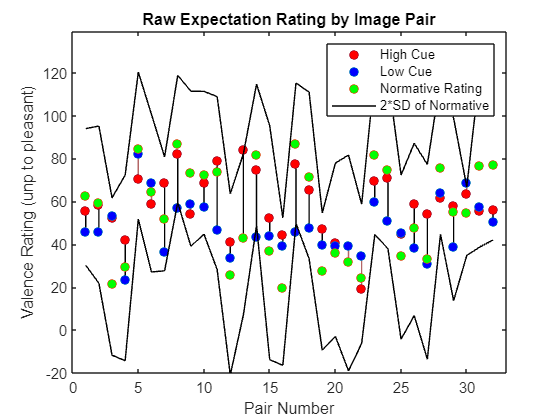

hi_sd = pair_table.stim_mean + (2*pair_table.stim_sd);
lo_sd = pair_table.stim_mean - (2*pair_table.stim_sd);
hold on;
highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

meandots = plot(pair_table.cue_mean, 'o', 'MarkerFaceColor', 'g');

sd_up = plot(hi_sd, 'k-');
sd_down = plot(lo_sd, 'k-');

xlabel('Pair Number');
ylabel('Valence Rating (unp to pleasant)')
hold off;
axis([0 33 -20 139])
legend([highdots lowdots meandots sd_up], {'High Cue', 'Low Cue', 'Normative Rating', '2*SD of Normative'})

Cue Effect (ordered from largest to smallest)

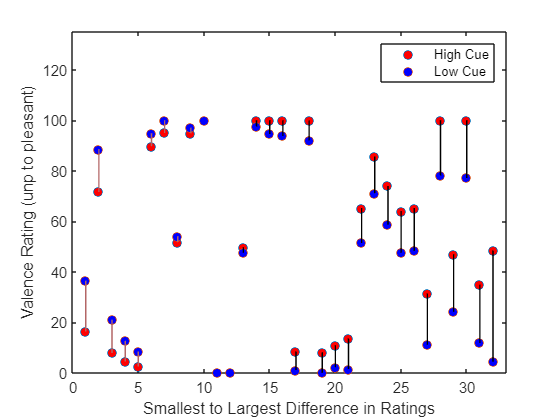

pair_table = sortrows(pair_table,"rating_diff","ascend");

pairs = [1:32]';

y = [pair_table.hi_val pair_table.lo_val];  % ratings, [high low]
x = [pairs pairs];  % pairs, [high low]


highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);


xlabel('Smallest to Largest Difference in Ratings');
ylabel('Valence Rating (unp to pleasant)')
hold off;

axis([0 33 0 135])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

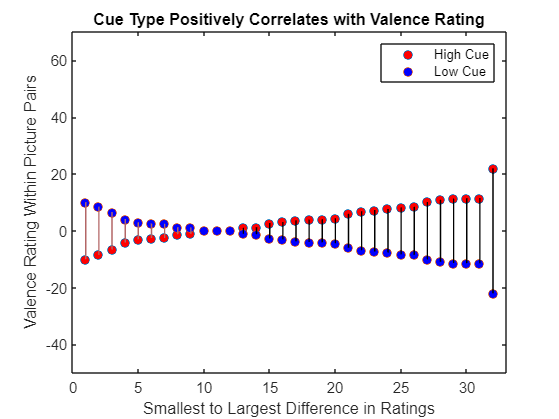

pair_table = sortrows(pair_table,"rating_diff","ascend");

pairs = [1:32]';

y = [pair_table.hi_val-pair_table.rating_mean pair_table.lo_val-pair_table.rating_mean];  % ratings, [high low]
x = [pairs pairs];  % pairs, [high low]


highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);

title('Cue Type Positively Correlates with Valence Rating')
xlabel('Smallest to Largest Difference in Ratings');
ylabel('Valence Rating Within Picture Pairs')
hold off;

axis([0 33 -50 70])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

Control of Cue Effect 

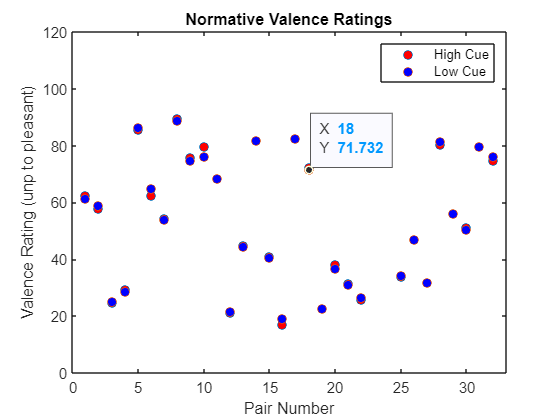



y = [hi_table.Valence_mean lo_table.Valence_mean];  % ratings, [high low]
x = [hi_table.Pair lo_table.Pair];  % pairs, [high low]

highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); hold off;

xlabel('Pair Number');
ylabel('Valence Rating (unp to pleasant)')
title('Normative Valence Ratings')
hold off;
axis([0 33 0 120])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

Averge Effect: 

% % Extract and compute normative H-L cue picture rating differences
normative_diff = pair_table.stim_diff;
% 
% Perform the regression model
X = [ones(size(normative_diff, 1), 1), normative_diff];
y = pair_table.rating_diff;
coeffs = regress(y, X);

% Extract the intercept term (effect of interest)
intercept = coeffs(1);

% Display the results
fprintf('Intercept (patient average H-L cue effect): %.4f\n', intercept);

Intercept (patient average H-L cue effect): 6.6746
